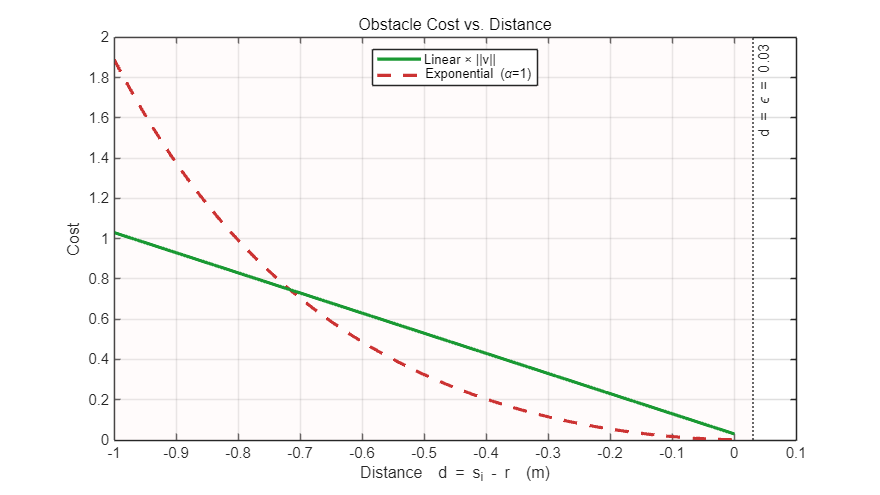

clear all;
%% 参数设置
epsilon = 0.03;      % 安全边界 ε
alpha   = 1;       % 指数项系数
v_norm  = 1.0;       % 线性项速度模长 ||v||

% 距离 d = s_i - r, 从 -2 到 0
d = linspace(-1, 0, 1000);

%% === 线性×速度代价 ===
J_lin = max(0, epsilon - d) * v_norm;

%% === 指数代价 ===
delta = epsilon - d;
J_exp = zeros(size(d));
mask  = (delta > 0);
J_exp(mask) = exp(alpha * delta(mask).^2) - 1;

figure('Color','w','Position',[100 100 800 450]);
hold on; grid on; box on;
set(gca,'Color','w');    % 坐标区背景也设为纯白

% 曲线
h1 = plot(d, J_lin, 'LineWidth',2.2,'Color',[0.1 0.6 0.2], ...
          'DisplayName','Linear × ||v||');
h2 = plot(d, J_exp, 'LineWidth',2.2,'LineStyle','--','Color',[0.8 0.2 0.2], ...
          'DisplayName',sprintf('Exponential (\\alpha=%g)',alpha));

% 阈值线（不进图例）
h_thr = xline(epsilon, ':', sprintf('d = \\epsilon = %.2f', epsilon), 'LineWidth',1.2);
set(get(get(h_thr,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');

% 标签
xlabel('Distance  d = s_i - r  (m)'); ylabel('Cost');
title('Obstacle Cost vs. Distance');

% 惩罚区背景（不进图例）
yl = ylim;
p = patch([-1 epsilon epsilon -1], [yl(1) yl(1) yl(2) yl(2)], ...
          [1 0.95 0.95], 'EdgeColor','none', 'FaceAlpha',0.3);
set(get(get(p,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');

% 只把曲线置顶
uistack([h1 h2],'top');

% 图例（固定，不随后续对象更新）
lgd = legend([h1 h2], 'Location', 'north');

lgd.AutoUpdate = 'off';

xlim([-1 0.1]);